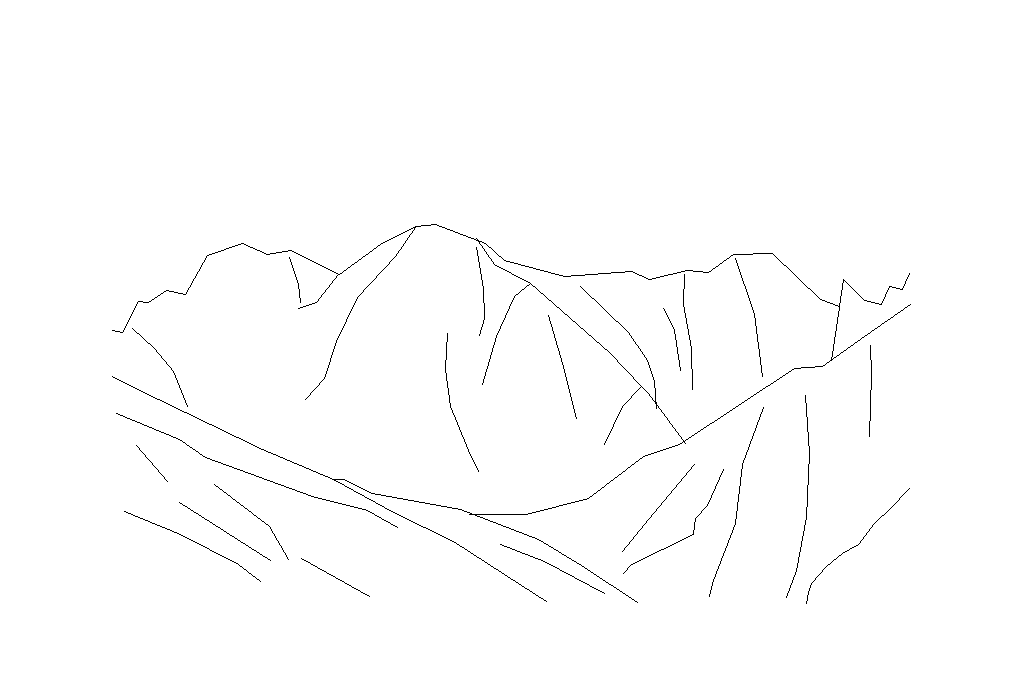

addpath(genpath('scripts'));
addpath(genpath('lib'));
addpath(genpath('3rdParty'))
load('data/LDStructures/mountains_vecLD.mat');
cute = vecLD(11);
imgLD = renderLinedrawing(cute);
figure;
imshow(imgLD);

MAT = computeMAT(imgLD,28);

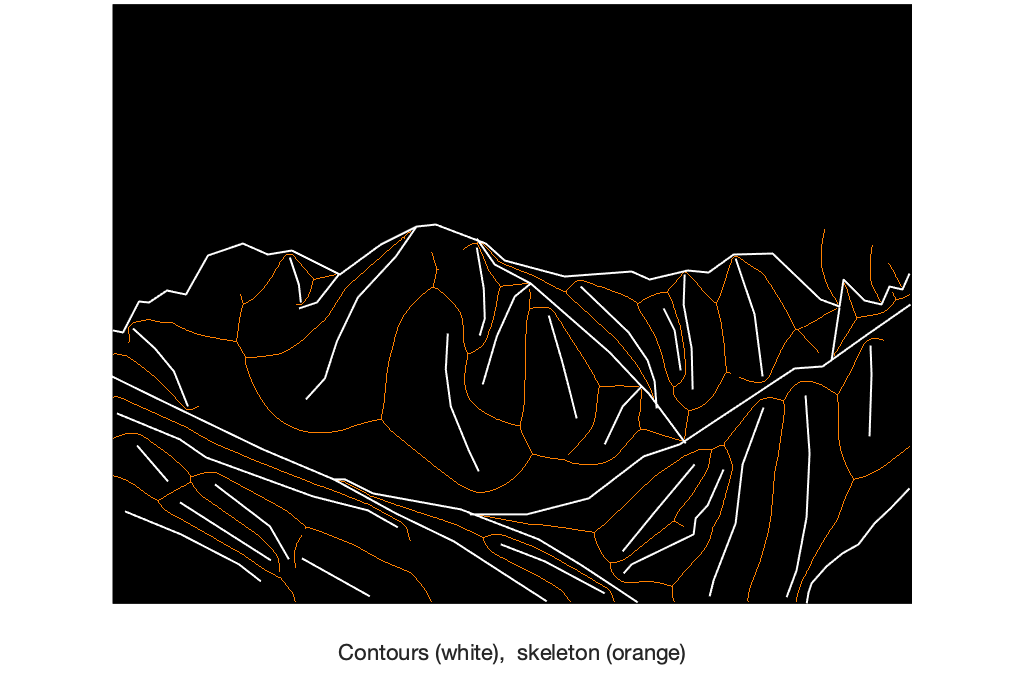

figure;
imshow(cat(3,MAT.skeleton,0.5*MAT.skeleton,zeros(size(MAT.skeleton))));
hold on;
drawLinedrawing(cute,1,'white')
% imshow(imoverlay(imcomplement(rgb2gray(imgLD)),MAT.skeleton,[1,0.5,0]))
xlabel('Contours (white),  skeleton (orange)')

figure;
imagesc(MAT.distance_map);
hold on;
drawLinedrawing(cute,1,'white')
c = colorbar;
c.Label.String = 'Distance to the closest contour'

c =   ColorBar (Distance to the closest contour) with properties:

    Location: 'eastoutside'
      Limits: [-1 270.6677]
    FontSize: 9
    Position: [0.8496 0.1661 0.0286 0.7022]
       Units: 'normalized'

  Show all properties


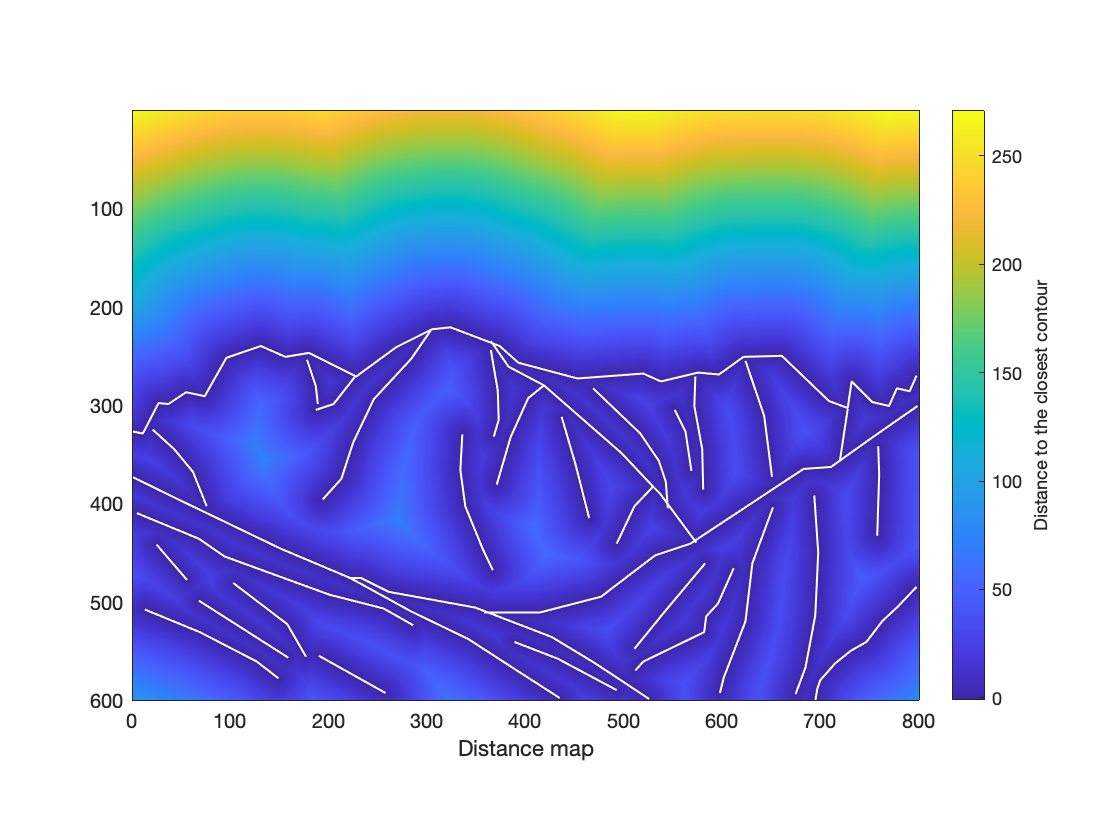

xlabel('Distance map')

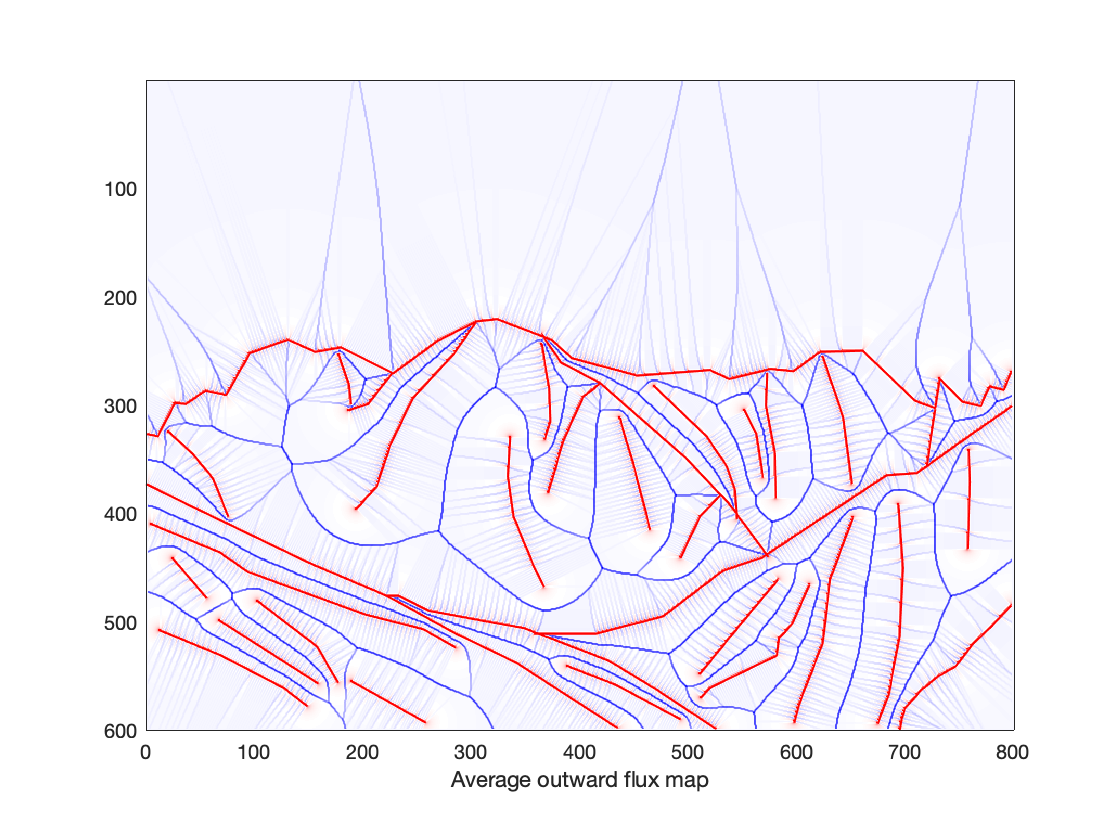

figure;
imagesc(-(MAT.AOF))
colormap redblue
hold on;
drawLinedrawing(cute,1,'red')
xlabel('Average outward flux map')

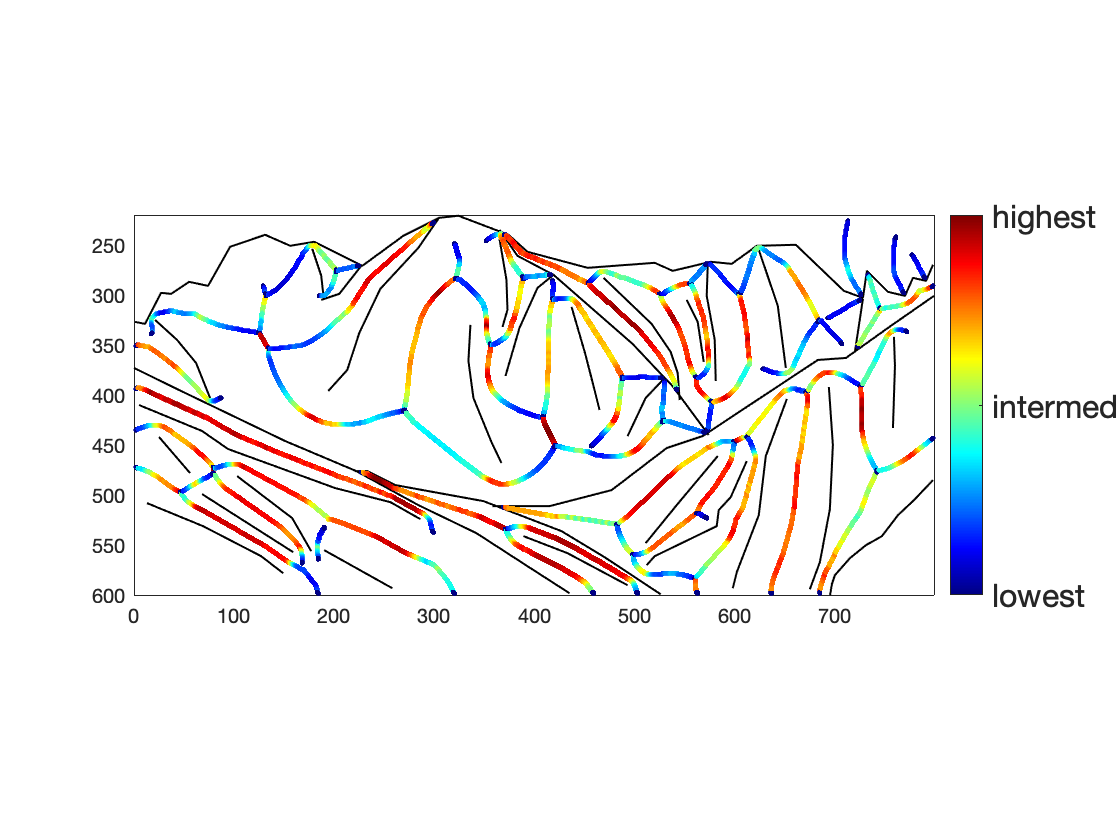

% options = 'parallelism', 'taper', 'separation', 'mirror'
figure;
[skeletonImageWithRating,skeletalBranches] = computeMATproperty(MAT,'parallelism');
drawMATproperty(skeletonImageWithRating,cute);

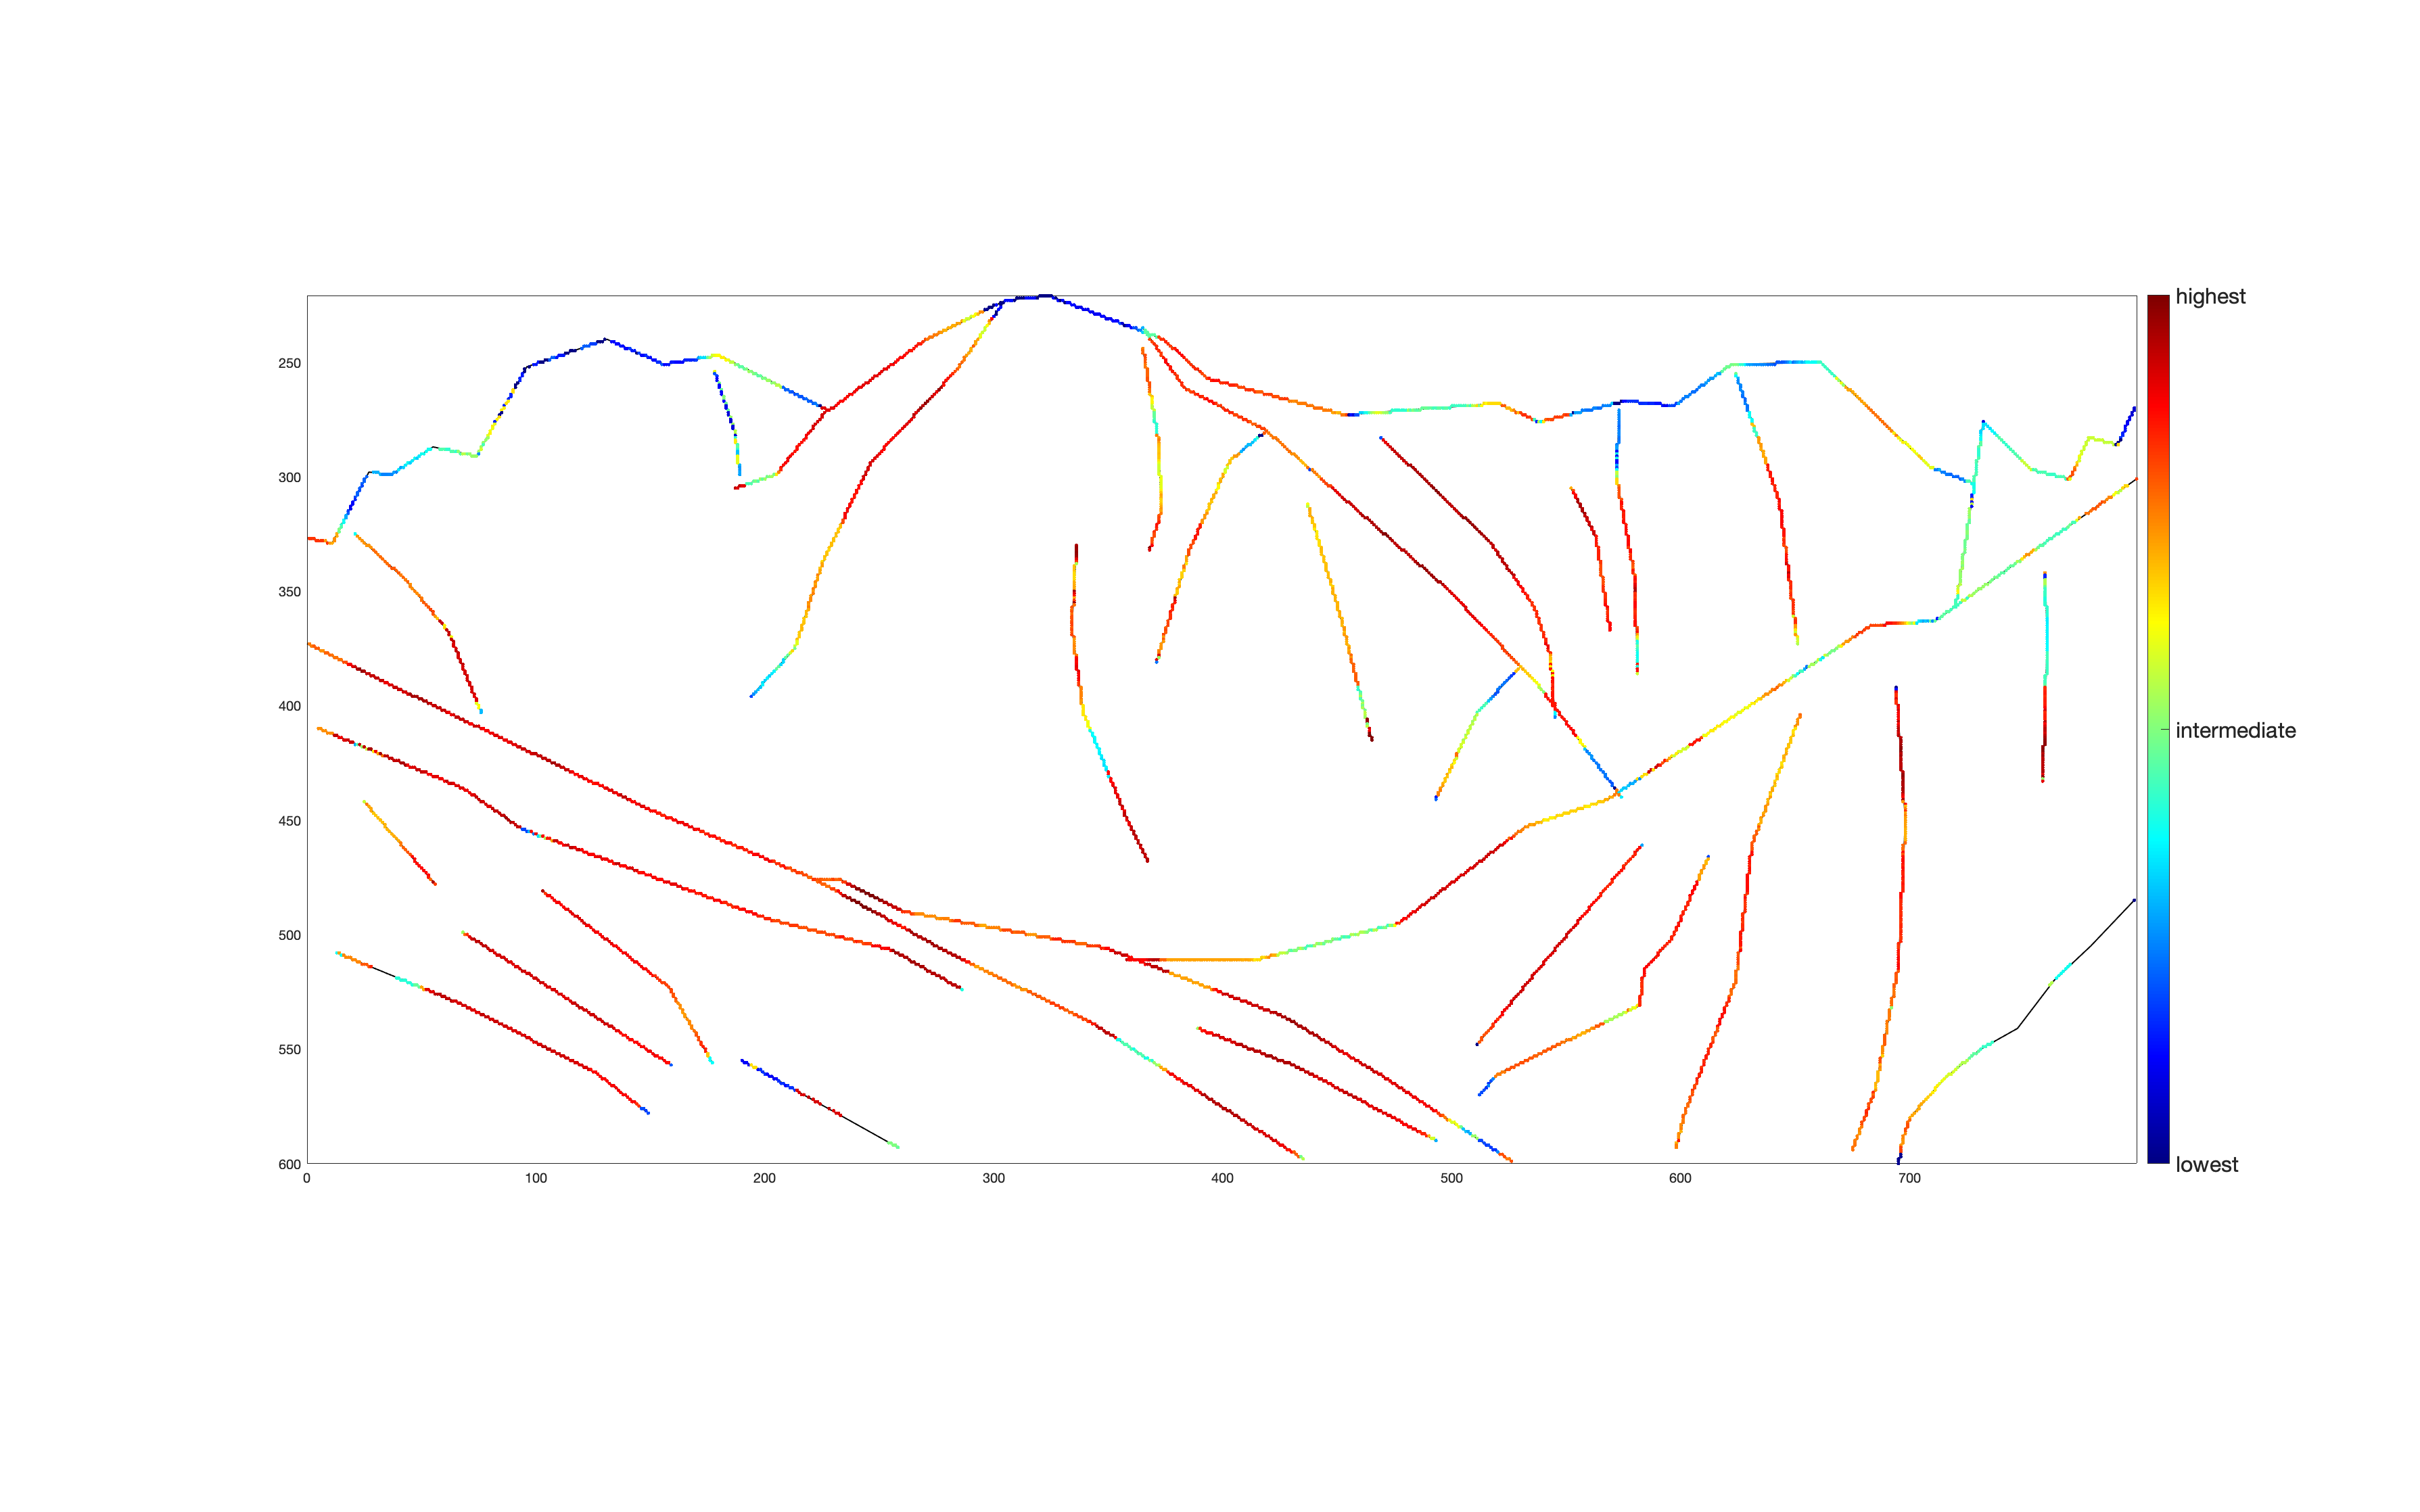

figure('units','normalized','outerposition',[0 0 1 1]);
contourImageWithRating = mapMATtoContour(skeletalBranches,imgLD,skeletonImageWithRating);
% drawMATproperty(contourImageWithRating);
drawMATproperty(contourImageWithRating,cute);

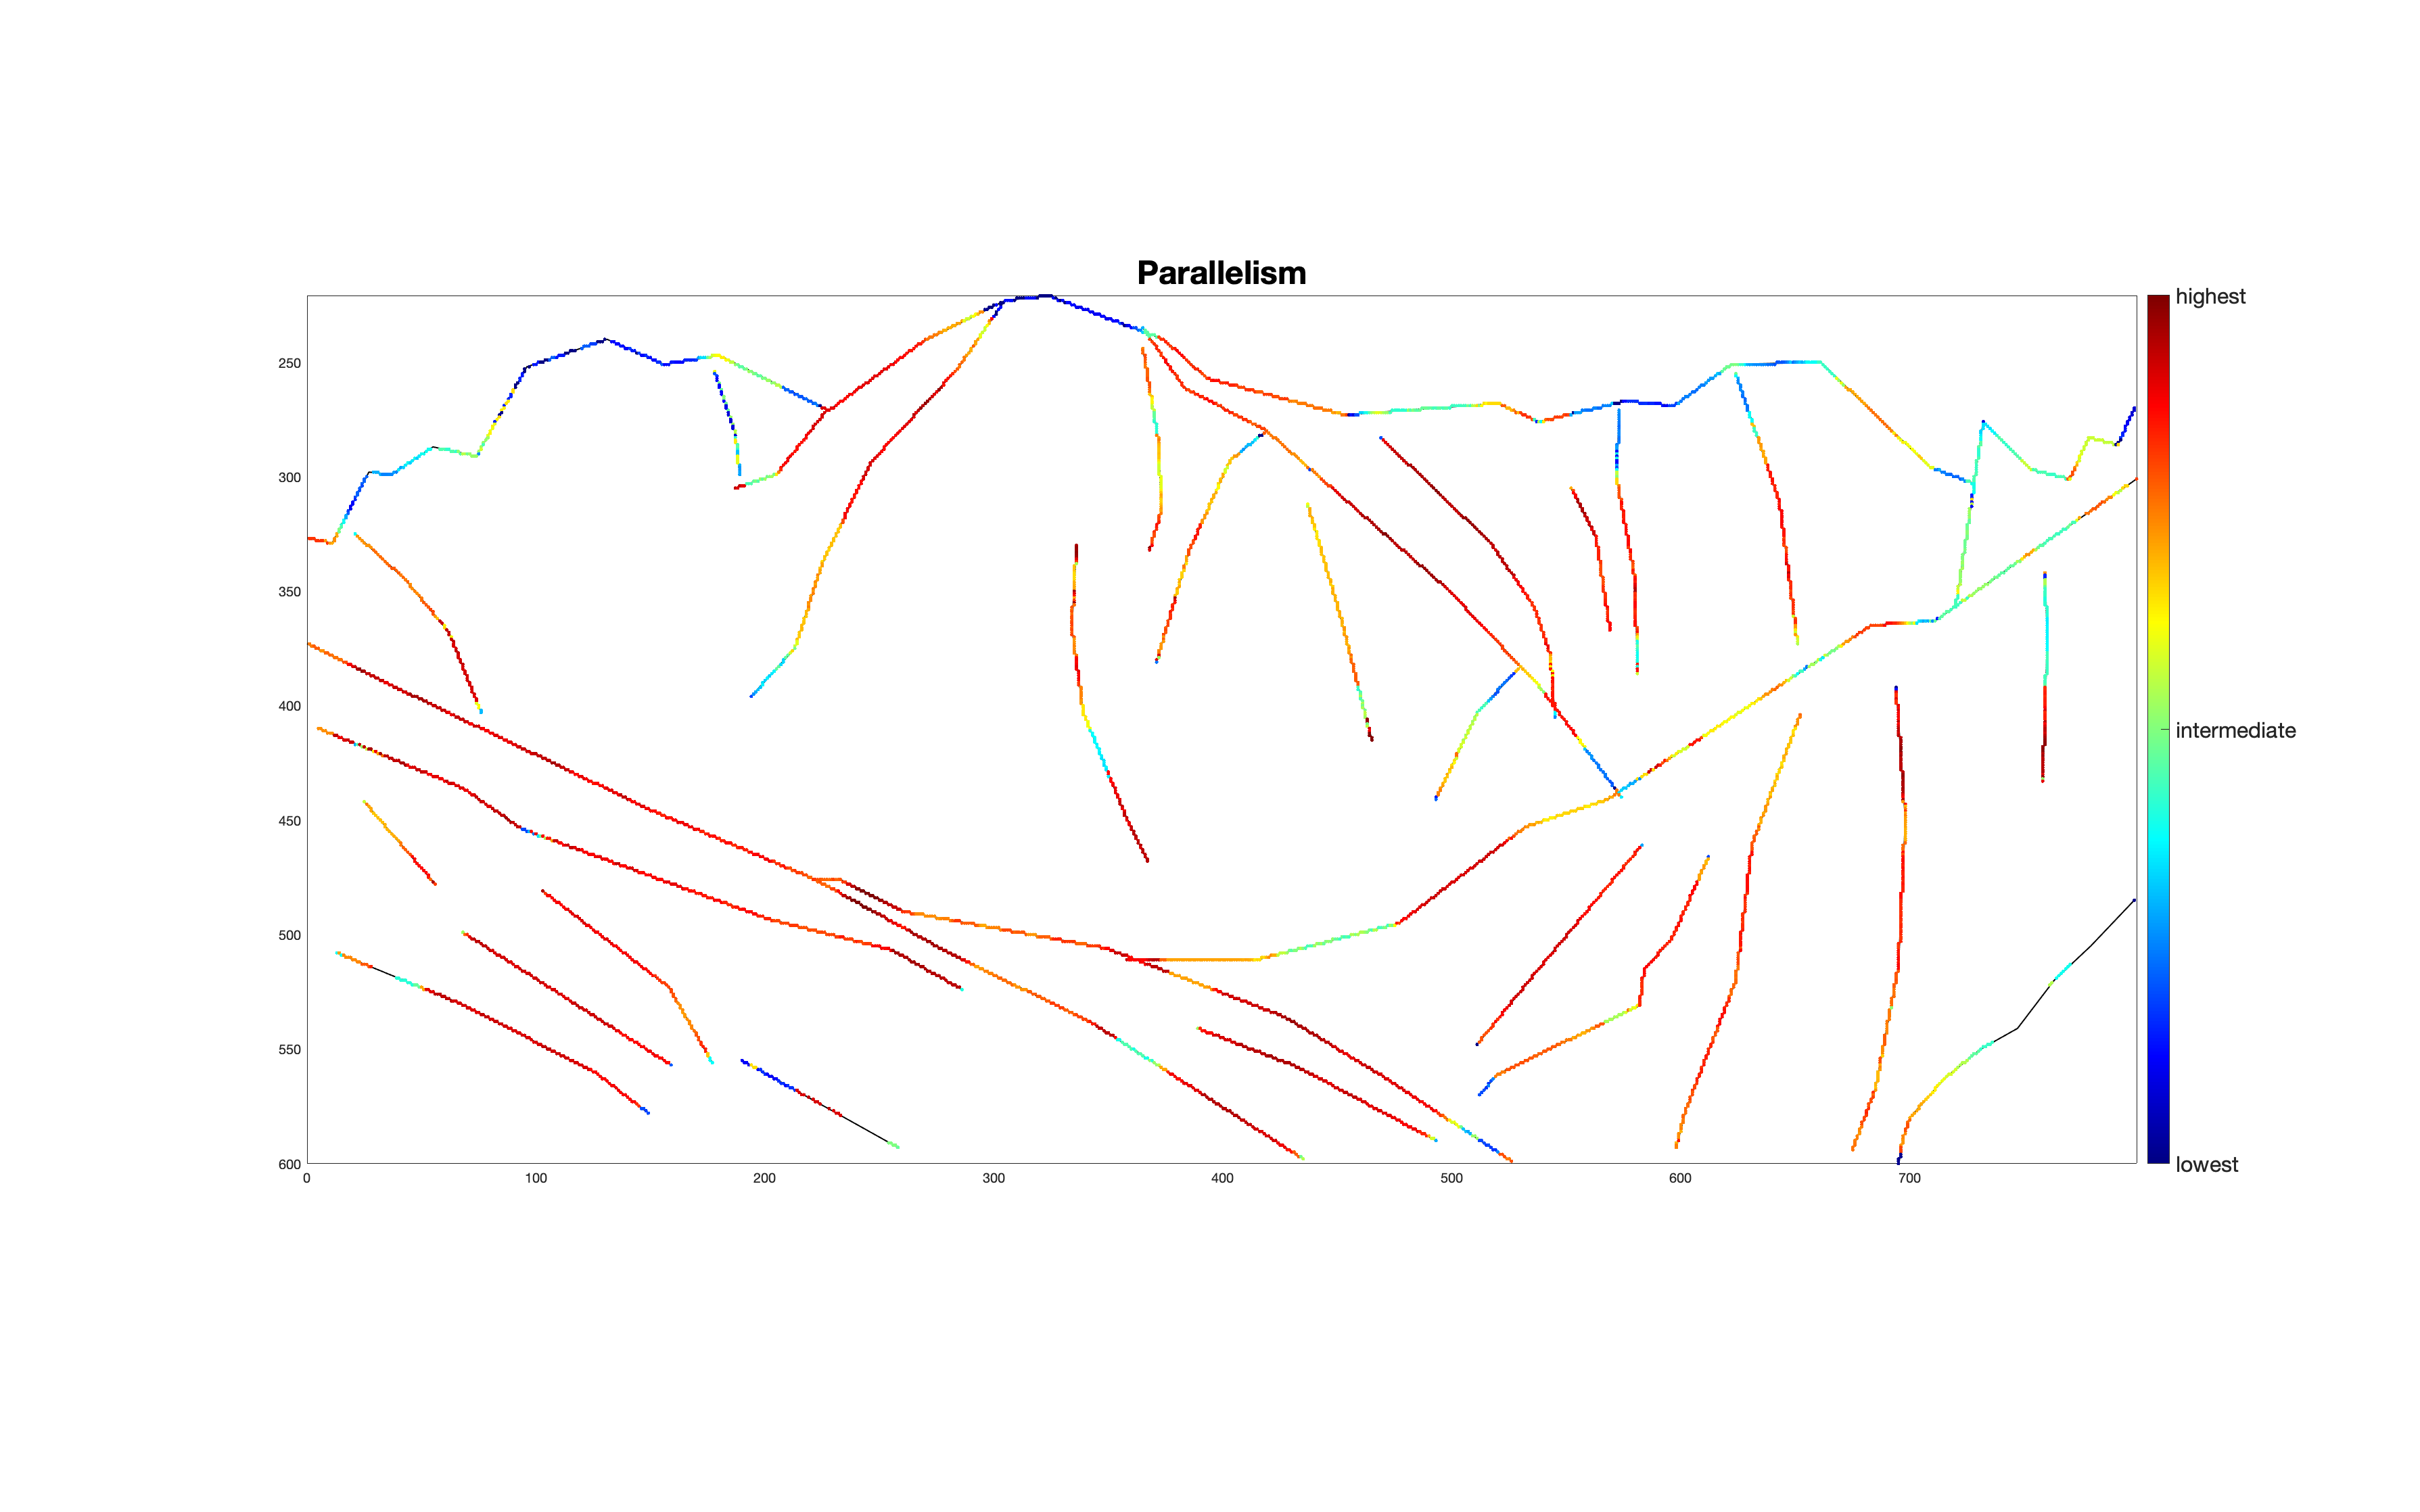


[MATcontourImages,MATskeletonImages,skeletalBranches]=computeAllMATproperties(MAT,imgLD);
drawMATproperty(MATcontourImages.mirror);
title('Mirror Symmetry','FontSize',24)
drawMATproperty(MATcontourImages.parallelism);
title('Parallelism','FontSize',24)

vecLD = MATpropertiesToContours(cute,MATcontourImages.mirror,'mirror');